# **EllipticF**

Jacobi form of the elliptic integral of the first kind

## Definition


$$\mathit{\mathbf{F}}\left(x\left|m\right.\right)\equiv \int_0^x \frac{\textrm{dt}\;}{\sqrt{\left(1-t^2 \right)\left(1-mt^2 \right)}}$$



$$\mathit{\mathbf{F}}\left(x,k\right)\equiv \mathit{\mathbf{F}}\left(x\left|k^2 \right.\right)$$


Domain: $1-x^2 \ge 0$ and $1-mx^2 \ge 0$. If $-\infty <m\le 1$ (or $|k|\le 1$) then $-1\le x\le 1$. If $m>1$ (or $k>1$)  then  $|x|<1/\sqrt{m}$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

$\mathit{\mathbf{F}}\left(-x\left|m\right.\right)=-\mathit{\mathbf{F}}\left(x\left|m\right.\right)$   (odd)

Special values:

$\mathit{\mathbf{F}}\left(0\left|m\right.\right)=0$,   $\mathit{\mathbf{F}}\left(1\left|m\right.\right)=K\left(m\right)$

$\mathit{\mathbf{F}}\left(x\left|-\infty \right.\right)=0$,   $\mathit{\mathbf{F}}\left(x\left|0\right.\right)=\sin^{-1} \left(x\right)$,   $\mathit{\mathbf{F}}\left(x\left|1\right.\right)={\mathrm{tanh}}^{-1} \left(x\right)$

Identities:


$$\mathit{\mathbf{F}}\left(x|m\right)=F\left({\mathrm{sin}}^{-1} \left(x\right)|m\right),\;\;\;|x|\le 1$$


*K *is complete elliptic integral of the first kind.

## Syntax

Y = EllipticF(X,K)

y = elF(x,k)

Y = mEllipticF(X,M)

y = melF(x,m)

## Description

**Y = EllipticF(X,K)** return the Jacobi form of elliptic integral of the first kind $\mathit{\mathbf{F}}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **EllipticF** is the wrapper function which calls the functions **elF** element-wise via the function **ufun2**.

**y = elF(x,k)** return the value of the Jacobi form of elliptic integral of the first kind  $\mathit{\mathbf{F}}\left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **elF** is the wrapper function which calls the functions **melF**.

**Y = mEllipticF(X,M)** returns the Jacobi form of elliptic integral of the first kind $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mEllipticF** is the wrapper function which calls the functions **melF** element-wise via the function **ufun2**.

**y = melF(x,m)** compute value of the Jacobi form of elliptic integral of the first kind  $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **melK **call the Carlson's function **rf **for calculation of $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[elF(x,k), EllipticF(x,k), melF(x,k^2), mEllipticF(x,k^2)]

ans =    0.529428627051906   0.529428627051906   0.529428627051906   0.529428627051906


Accuracy.

fprintf('%.16g\n',elF(0.5,1.2)) %  Maple 18D  =  0.5631345956371007 23

0.5631345956371008


Special values

m = -2;
x = -0.5;  % |x| <= 1
melF(0,m)

ans = 0

disp(melF(1,m) - melK(m))  % m < 1 !!!

     0



melF(x,-inf)

ans = 0

disp(melF(x,0) - asin(x)) 

     0



disp(melF(x,1) - atanh(x))

     0



melF(x,inf)  % x = 0

ans = NaN

Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mEllipticF(-x,m) + mEllipticF(x,m))

     0



disp(mEllipticF(x,m) - mpEllipticF(asin(x),m))

    -1.665334536937735e-16



k = 0.99995;
disp(EllipticF(1/sqrt(1+sqrt(1-k^2)),k)-elK(k)/2)

     2.309263891220326e-13



**Vector input**

k = [0.1, 0.5, 0.89, 0.99995];
disp(EllipticF(1./sqrt(1+sqrt(1-k.^2)),k)-EllipticK(k)/2)

   1.0e-12 *

                   0                   0  -0.000222044604925   0.230926389122033



**Matrix input**

k = [0.1, 0.5, 0.89; -0.1, -0.97, 0.99995 ]';
disp(EllipticF(1./sqrt(1+sqrt(1-k.^2)),k)-EllipticK(k)/2)

   1.0e-12 *

                   0                   0
                   0  -0.000444089209850
  -0.000222044604925   0.230926389122033



## **Plot **

**Example 1**

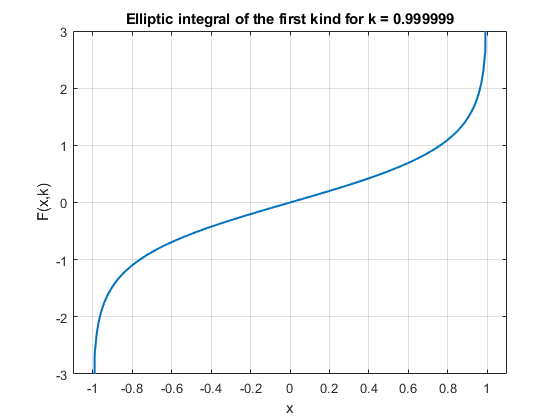

figure
x=-1:0.01:1;
k = 0.999999;
plot(x,EllipticF(x,k),'LineWidth',1.5)
xlabel('x')
ylabel('F(x,k)')
xlim([-1.1 1.1])
ylim([-3 3])
title(sprintf('Elliptic integral of the first kind for k = %g',k))
grid on

**Example 2**

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mEllipticF(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg,'Location','Best')

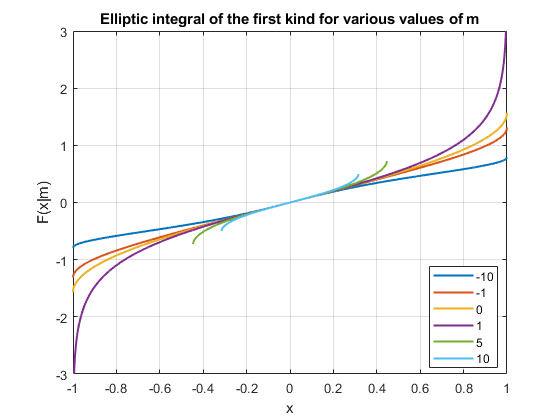

title('Elliptic integral of the first kind for various values of m')
xlabel('x')
ylabel('F(x|m)')

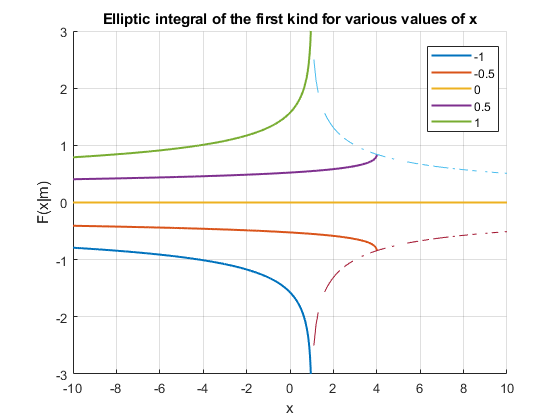

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticF(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral of the first kind for various values of x')
xlabel('x')
ylabel('F(x|m)')
M = 0:0.1:10;
F = mEllipticF(1./sqrt(abs(M)),M);
plot(M,F)
plot(M,-F)
hold off

**Example 3**

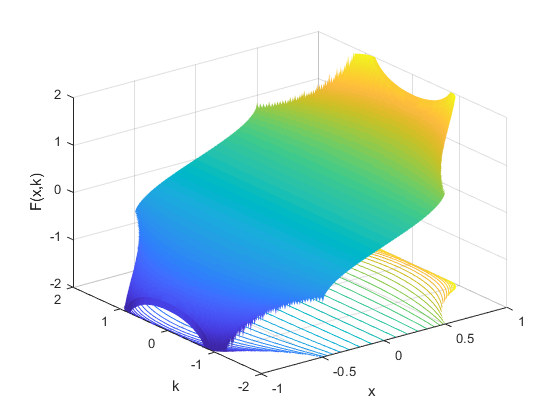

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,EllipticF(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('F(x,k)')
zlim([-2 2])
grid on

**Example 4**

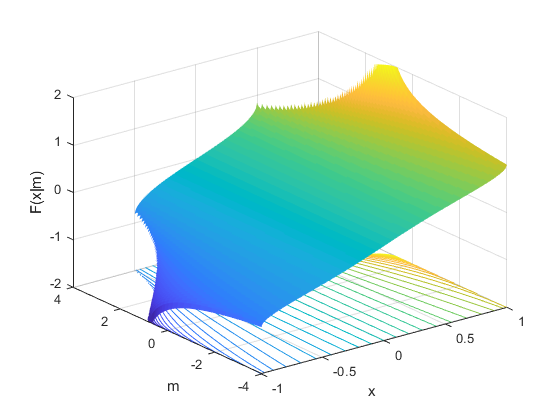

figure
x=-1:0.01:1;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mEllipticF(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('F(x|m)')
zlim([-2 2])
grid on

**Example 5**

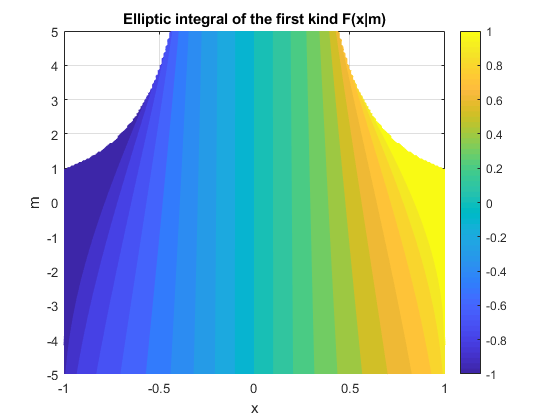

figure
f = @(x,m)mEllipticF(x,m);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral of the first kind F(x|m)')
colorbar
xlabel('x')
ylabel('m')
grid on

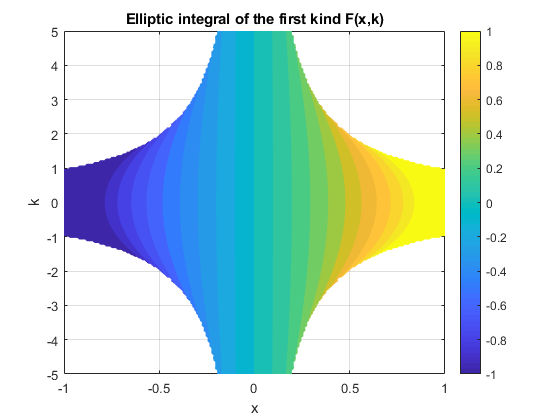

figure
f = @(x,k)EllipticF(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral of the first kind F(x,k)')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also